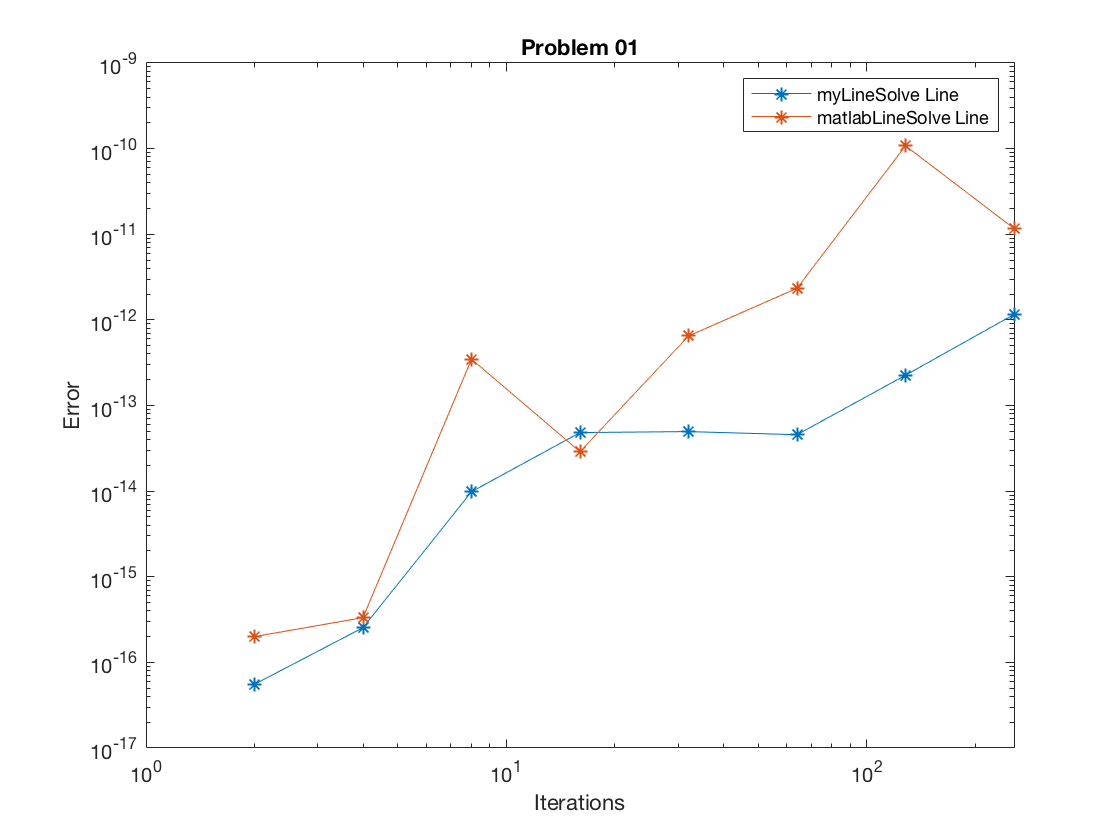

% Problem 01A
% Worked with Andy for logic of the functions
k = 1:1:8;
n = 2.^k;
rng(5);

%define values of A b (these are the values we determined previously)
% doing a for lopp to go through each n value
for i = 1:numel(n)
    N = n(i);
    A = rand(N);
    % x exact has the value we will compute gainst
    x_exact = rand(N,1);
    b = A * x_exact;
    %compute each case
    case1 = linsolve(A,b);
    case2 = my_linsolve(A,b);
    case3 = my_linsolvePivots(A,b);
    % compute each error
    error1(i) = abs(norm(x_exact - case1));
    error2(i) = abs(norm(x_exact - case2));
    error3(i) = abs(norm(x_exact - case3));
end

% Graph Making
loglog(n,error1,'-*',n,error2,'-*');
title('Problem 01');
legend('myLineSolve Line','matlabLineSolve Line');
xlabel('Iterations');
ylabel('Error');

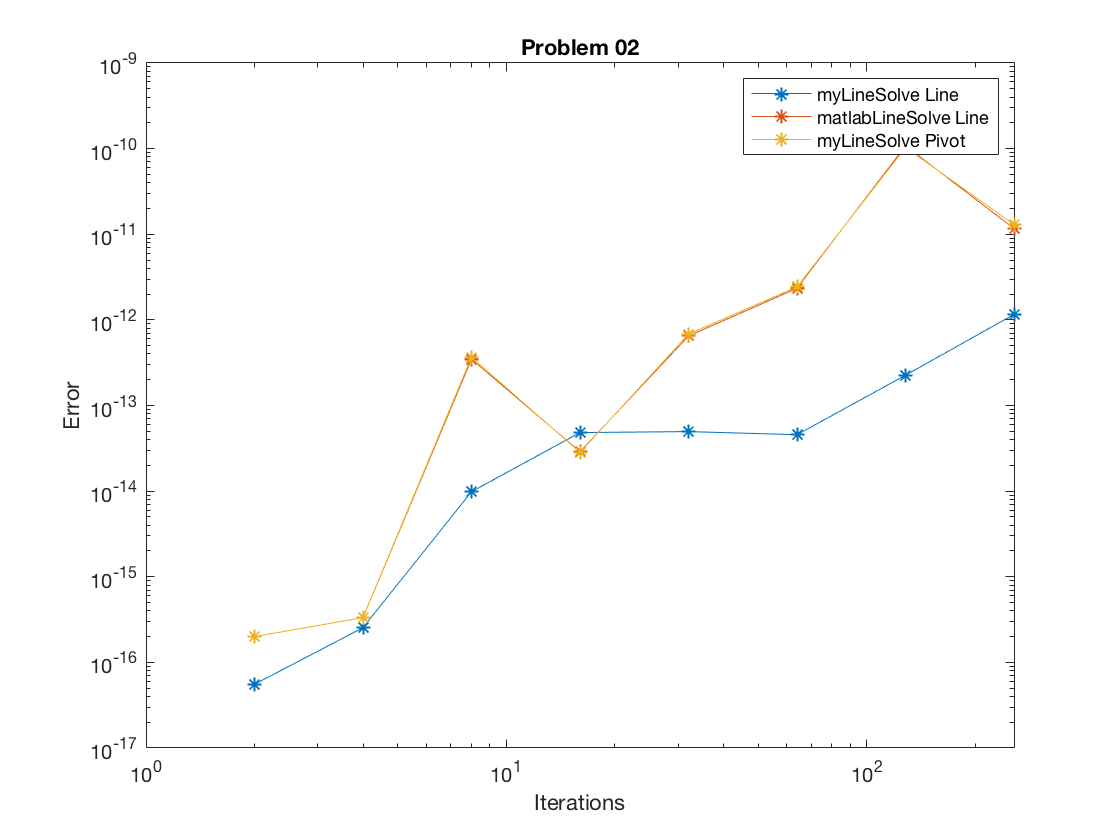


%Problem 02
%the matlab linsolve and pivot are about the same.
loglog(n,error1,'-*',n,error2,'-*',n,error3,'-*');
title('Problem 02');
legend('myLineSolve Line','matlabLineSolve Line','myLineSolve Pivot');
xlabel('Iterations');
ylabel('Error');

function x = my_linsolve(A,b)
n = size(A,1);
A = [A,b]; 

for j = 1:n
    for i = j+1:n
        A(i,:) = A(i,:) - A(i,j)/A(j,j)*A(j,:);
        A(i,j) = 0;
    end
end

for j = n:-1:1

    for i = 1:j-1
        A(i,:) = A(i,:) - A(i,j)/A(j,j)*A(j,:);
        A(i,j) = 0; 
    end
end
x = A(1:n,n+1) ./ diag(A(1:n,1:n));
end

function x = my_linsolvePivots(A,b)
%   A = n-by-n array
%   b = n-by-1 array
n = size(A,1);
% get system dimension
%form  matrix
A = [A, b];
%for each variable
    for j = 1:n
        %partial swap/pivot

        m = max(abs(A(j:end,j)));
        k = j + find(m) - 1; %search non-zeroes in 1st col (diagonal)
        if isempty(k)
            error('breakdown');
        else
            k = k(1);
        end
        A([j,k],:) = A([k, j], :);
        %eliminate variable j from equations j+1, ... , n
        for i = j+1:n
            A(i, :) = A(i, :) - A(i, j)/A(j, j) * A(j,:);
            %A(i, j) = 0; %flush all zeroes
        end
    end
    %introduce zeros above diagonal
    %for each variable in reverse; Gausss-jordan elimination
    for j = n:-1:1
        %eliminate variable j from equation 1,2, ..., j-1
       for i = 1:j-1
           %eliminate variable j from equation i using equation j
           A(i, :) = A(i, :) - A(i, j)/A(j, j) * A(j,:);
           A(i,j) = 0;
       end
    end
    %solving the diagonal linear system
    x = A(1:n, n+1) ./ (diag(A(1:n, 1:n))); %from afternoon lecture
    %x = A(:, end) ./ diag(A(:,1:end-1)); %from the morning lecture
end